# How to Develop a Machine Learning Classifier

As seen in ["How to Develop a Machine Learning Classifier,"](https://www.mathworks.com/videos/how-to-develop-a-machine-learning-classifier-with-matlab-1687171767480.html) in this example we'll use features extracted from fluorescence intensity time histories to train a machine learning model to classify if tissue regions might be cancerous.

### Examine Labeled Intensity Time Histories

Fluorescence intensity time histories can be collected and labeled using the [Fluorescence Tracker App](https://www.mathworks.com/matlabcentral/fileexchange/89679-fluorescence-tracker-app/).

% Load data (if not already exported from Fluorescence Tracker App)
if ~exist("Iregion","var")
    load(fullfile("data","AMST_0001.mat"),"time","Iregion","LabelTable")
end
addpath("helper") % add helper functions to path

% Extract and smooth labeled data
gid = LabelTable.("Grid Region");
Ismooth = smoothdata(Iregion(:,gid),1,SmoothingFactor=0.1);

% Plot time histories for each label
can = (LabelTable.Label=="Cancer");
figure
hn = plot(time,Ismooth(:,~can), LineWidth=1, Color=[0.2 0.5 1]);
hold on; grid on
hc = plot(time,Ismooth(:,can), LineWidth=1, Color=[0.9 0.3 0]);

legend([hn(1) hc(1)],["Negative","Cancer"],Location="southeast")
title("Smoothed Intensity Time Histories")
xlabel("Video Time (sec)")
ylabel("Fluorescence Intensity [0 - 255]")
axis padded

### Extract Features of Interest

We'll extract and consider the following features of interest:

- `Ibase` - base intensity value (just before start of ICG dye absorption)

- `Ipeak` - peak intensity value

- `dThalf` - time to reach half peak intensity (from start of absorption)

- `dTpeak` -  time to reach full peak intensity (from start of absorption)

- `IdecayXs` - intensity value "`X`" seconds after peak intensity

% Select and extract features of interest
dTdecay = [50 100 145]; % time since peak intensity
features = getPredictors(time,Ismooth,dTdecay);
disp([LabelTable(:,"Label") features(:,2:end)])

% Add selected features to plot
plotFeatures(features)
title("Selected Features")

### Develop a Model using the Classification Learner

The above process was repeated for a total of 22 patients.  We'll use 20 of the videos for training (10 with cancer and 10 without) and set aside 2 videos for testing (1 with cancer and 1 without).  On average, each video labeled about a dozen grid regions. "Negative" regions were collected from all videos, with an even mix of benign lesions and healthy tissue.

% Load training and testing data sets
load(fullfile("data","FluorescenceDataSets.mat"),"trainData","testData")

% Check if training data set is balanced
TrainingCount = countlabels(trainData.Label)
TestCount = countlabels(testData.Label)

Open the Classification Learner app from the APPS tab to begin developing a classifier.

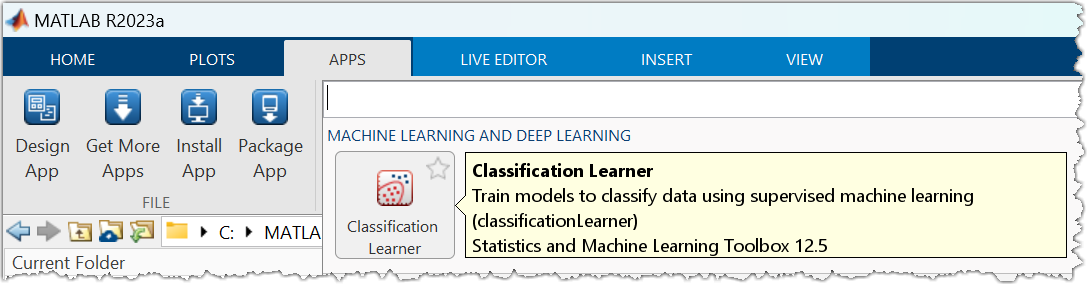

### Export and Test the Trained Model

We can reproduce the test confusion matrix we created in the Classification Learner app by exporting the model and using it to make predictions on the test data.

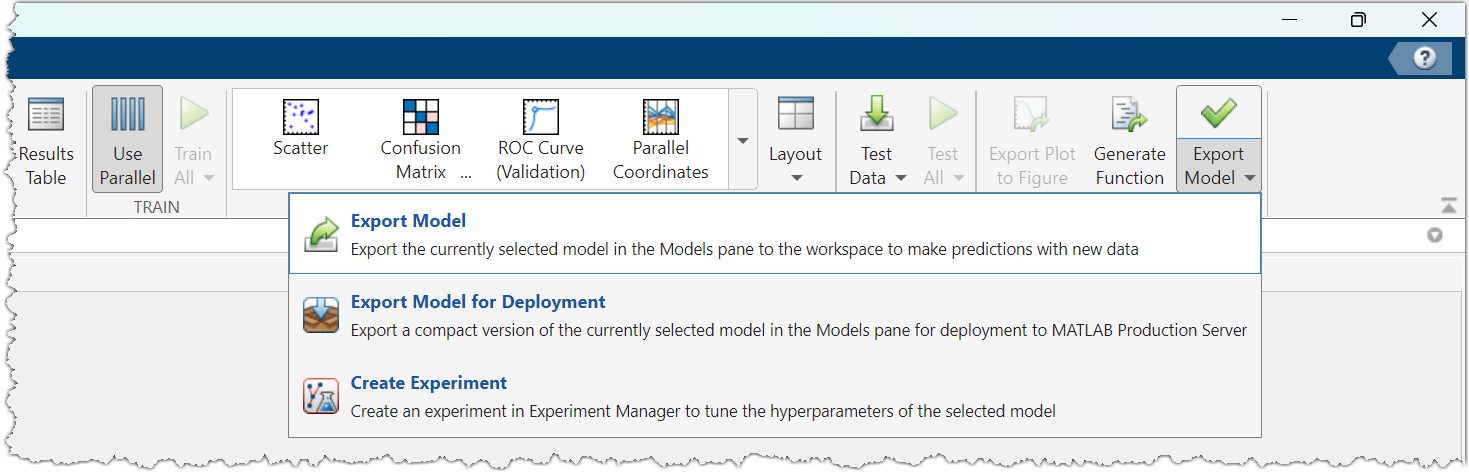

% Load model (if not already exported from Classification Learner)
if ~exist("trainedModel","var")
    load(fullfile("data","KnnClassifier.mat"),"trainedModel")
end

% Make predictions on test data
predLabel = trainedModel.predictFcn(testData);

figure
confusionchart(testData.Label,string(predLabel))
title("Test Accuracy = "+100*mean(testData.Label==predLabel)+"%")

### Use Scores to Create Prediction Heatmap

The prediction function can also provide the classification scores as a second output.  The classification `score(i,j)` represents the posterior probability that the `i`th observation belongs to class `j`.  Since we gathered intensity time histories from a grid of regions across the entire video frame, we can use the classification scores to create a prediction probability heatmap.  (If there was excessive camera movement, intensity data may not be available along some edges due to image warping during the registration process.)

% Setup color map: Negative -> blue, Cancer -> red
classNames = getClassNames(trainedModel);
cmap = 255*turbo;
if (classNames(1) == "Cancer")
    cmap = flip(cmap);
end

testIds = unique([testData.Patient]);
for k = 1:numel(testIds)
    % Load intensity time histories for each grid region
    file = fullfile("data",testIds(k)+".mat");
    load(file,"time","Iregion","cframe1","region")

    % Extract features for each grid region
    Ismooth = smoothdata(Iregion,1,SmoothingFactor=0.1);
    features = getPredictors(time,Ismooth,dTdecay);
    val = ~any(isnan(features.Variables),2);
    features = features(val,:); % only use valid regions

    % Use classification scores to create prediction heatmap
    [~,score] = trainedModel.predictFcn(features);
    overlay = predictionOverlay(cframe1,region,val,score,cmap);

    fig = figure;
    imshow(overlay)
    colormap(cmap/255); clim([-1 1])
    cbar = colorbar("south",Ticks=[-1 1]);
    cbar.TickLabels = classNames;
    cbar.Position(2) = 0.05;
    title("Prediction Heatmap")

    labels = testData.Label(testData.Patient==testIds(k));
    if ismember("Cancer",labels)
        lesion = "Cancer";
    else
        lesion = "Benign";
    end
    subtitle("Lesion Biopsy: "+lesion, Visible="on")
    fig.Position(4) = 1.2*fig.Position(4); % increase height
end

**Helper Function**

Helper function to extract class names regardless of model type.

function classNames = getClassNames(trainedModel)
fld = fields(trainedModel);
idx = contains(fld,"Classification");
mdl = trainedModel.(fld{idx});
classNames = string(mdl.ClassNames);
end

*Copyright 2023 The MathWorks, Inc.*